# **Introductory script illustrating how to generate an ISETBio scene representing a stimulus rendered on a particular display**

#### **See also**: 

#### **Copyrigh**t: ISETBio Team, Nicolas P. Cottaris

# OUTLINE

 **   Step 1.** Create a display object (presentation display)

 **   Step 2.** Create a scene object describing the stimulus

   ** Step 3.** Create a scene object of the stimulus as realized on the presentation display

# **Step 1.** Create a display object

### Initialize a display object

Start with an existing display specification, here an Apple LCD display and place it at 57 cm from the subject

presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 0.57);

### Three key properties of a display's primaries (guns)

- spectral power distribution, which is the emmitted power as a function of wavelength

- gamma curve, which is the relationship between the linear (input) primary value and the activation (output) of the primary 

- chromaticity coordinates and maximum luminance

In ISETBio, we interact with objects via **set **(write) and **get **(read) functions. These functions accept input arguments specifiying the property whose value we want to write or read. We can get some information about what the available property names are by typing **doc** and the setter/getter function name, for example, **doc displayGet**

### Step 1.1 **Retrieve and plot the display primaries' spectral power distribution (SPD)**

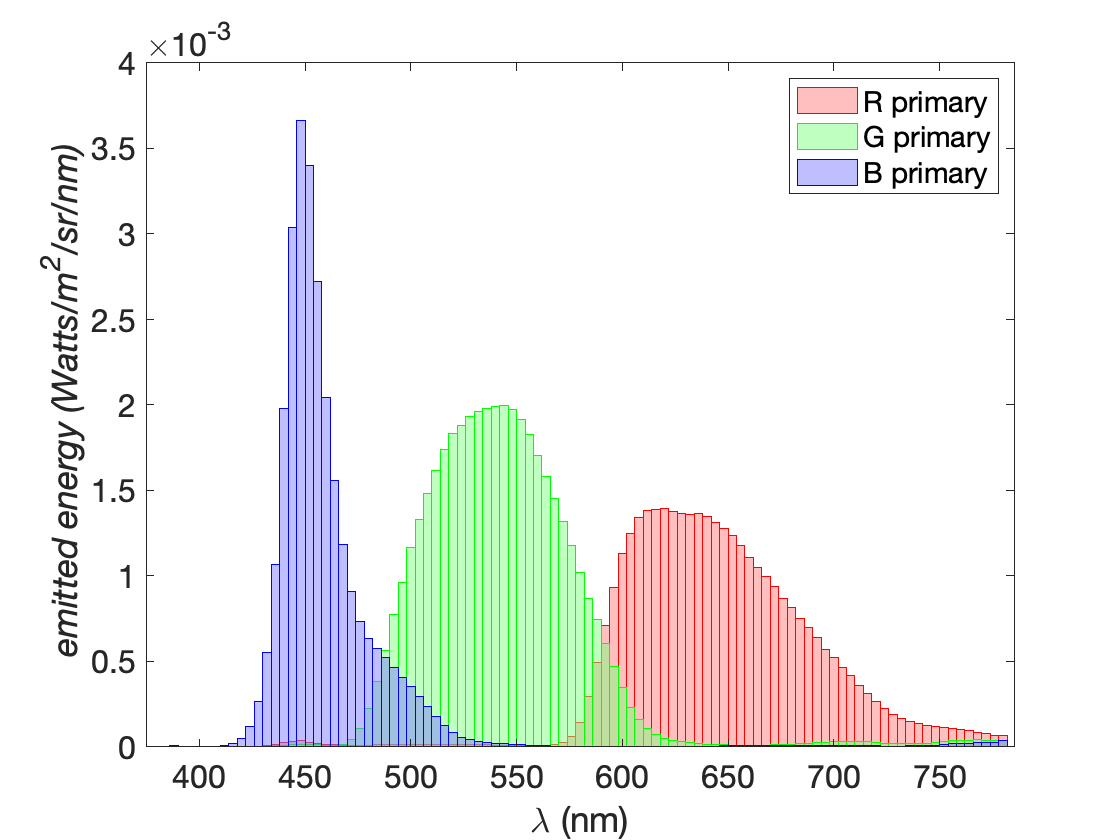

% retrieve the wavelength support
wavelengthSupport = displayGet(presentationDisplay, 'wave');
% retrieve the SPDs
spds = displayGet(presentationDisplay, 'spd primaries');
% display the SPDs
visualizeDisplaySPD(wavelengthSupport, spds); 

### Step 1.2 Retrieve and plot the display primaries' gamma, or lookup table (LUT)

The LUT function maps linear RGB values (settings values, or RGB) to output light intensities (primary values-rgb)

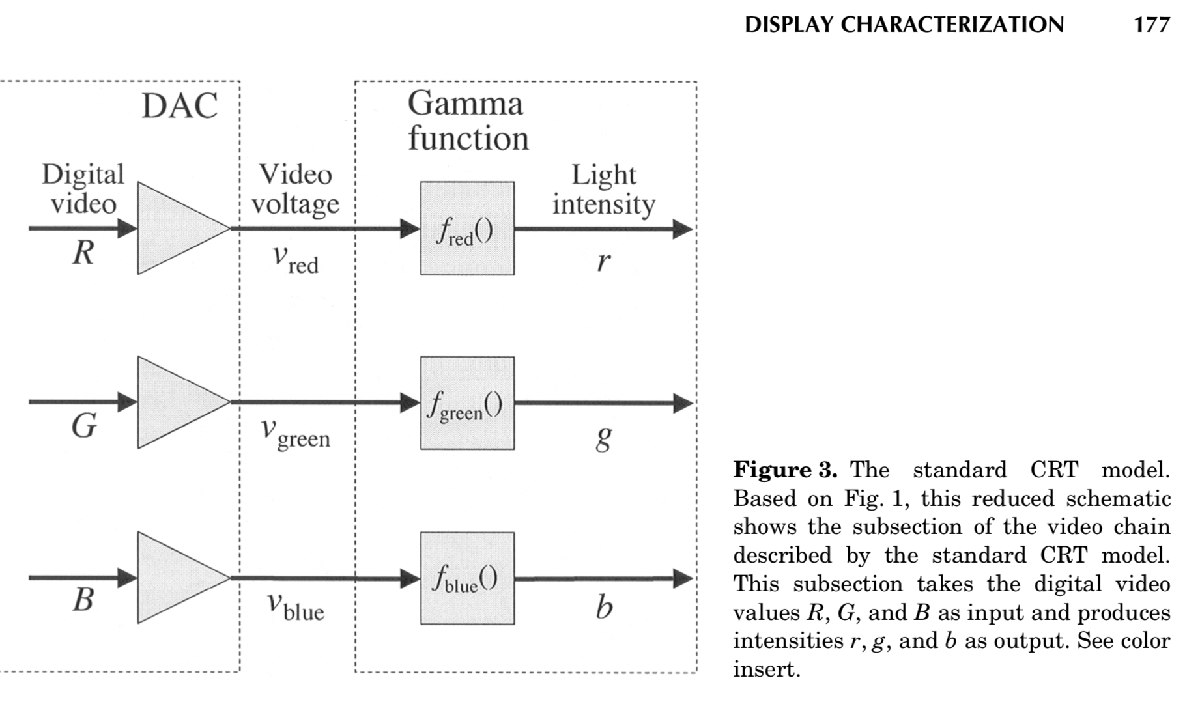

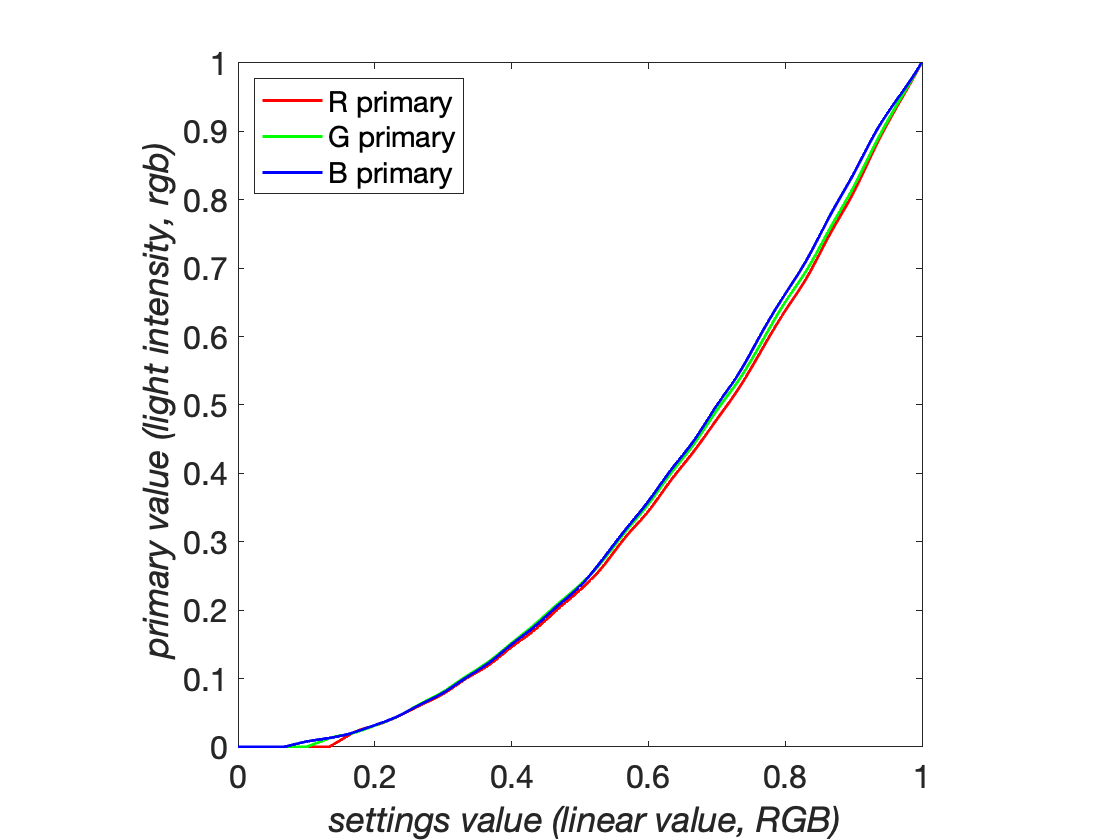

% retrieve the gamma table, or LUT, which maps 
% linear RGB values (primary rgb values) -> light intensities (settings values)
gammaTable = displayGet(presentationDisplay, 'gamma table');
% display the LUT
visualizeDisplayLUT(gammaTable); 

### Step 1.3 Retrieve and plot the display's chromatic gamut

The SPDs of the display's R,G,B primary determine the display's gamut, which is the range of colors and luminances that can be realized of the display.

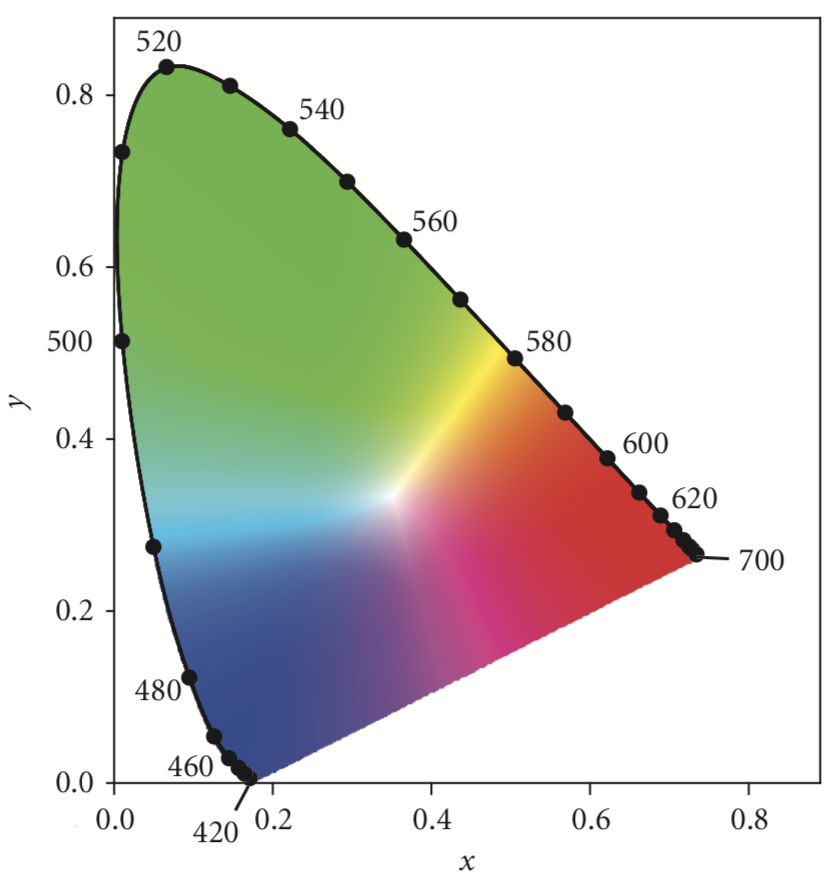

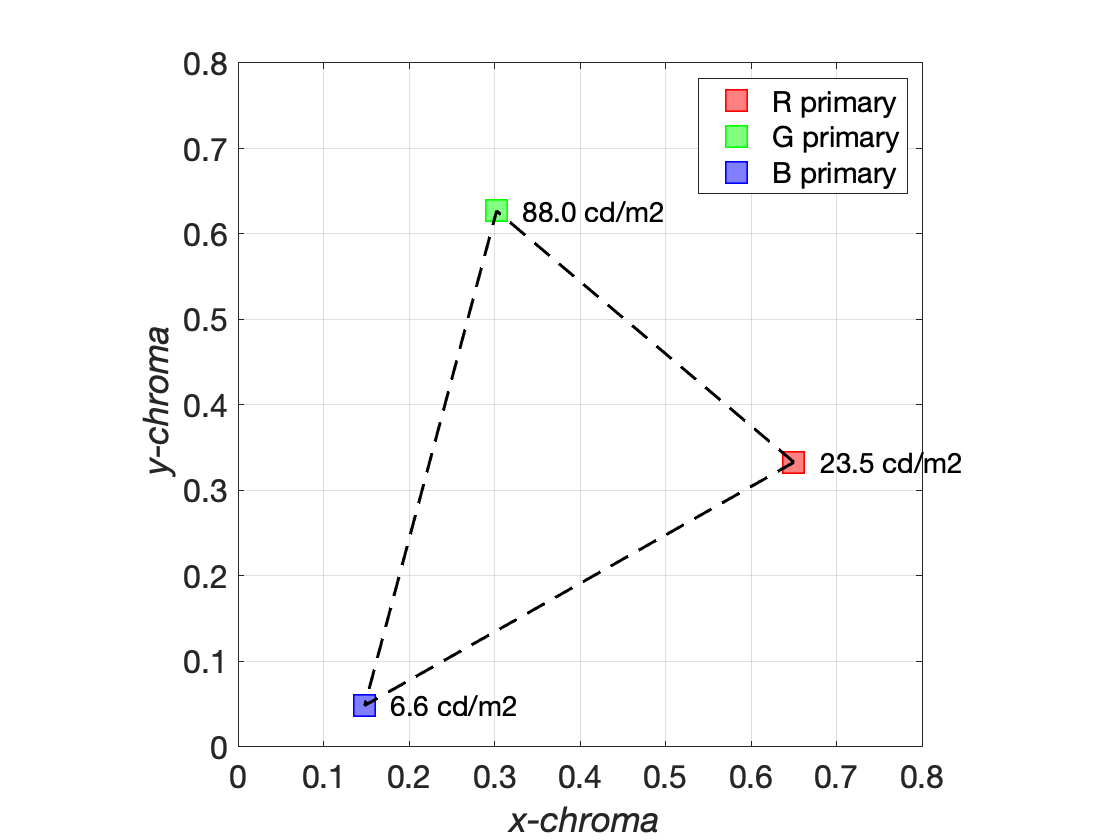

% retrieve the XYZ tristimulus values of the display's RGB primaries
primariesXYZ = displayGet(presentationDisplay, 'primaries xyz');
% display the corresponding chromaticity coordinates and maximum luminances
visualizeDisplayGamut(primariesXYZ)

# **Step 2.** Create a scene object describing the stimulus

### Step 2.1 Specify parameters for a desired stimulus

Here we specify various parameters for an achromatic Gabor stimulus.

%% parameter struct for a Gabor stimulus 
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg', 10, ... % 10 cycles/deg
    'orientationDegs', 0, ...               % 45 degrees
    'phaseDegs', 90, ...                    % spatial phase degrees
    'sizeDegs', 0.4, ...                    % 0.x4 x 0.4 size
    'sigmaDegs', 0.2/3, ...                 % sigma of Gaussian envelope
    'contrast', 0.6,...                     % 0.6 Michelson contrast
    'meanLuminanceCdPerM2', 40, ...         % 40 cd/m2 mean luminance
    'pixelsAlongWidthDim', [], ...          % pixels- width dimension
    'pixelsAlongHeightDim', [] ...          % pixel- height dimension
    )

stimParams = struct with fields:
    spatialFrequencyCyclesPerDeg: 10
                 orientationDegs: 0
                       phaseDegs: 90
                        sizeDegs: 0.4000
                       sigmaDegs: 0.0667
                        contrast: 0.6000
            meanLuminanceCdPerM2: 40
             pixelsAlongWidthDim: []
            pixelsAlongHeightDim: []


### Step 2.2 Compute the number of stimulus pixels

Note that we did not specify the number of pixels along the width and height as this depends on the pixel size of the presentation display. Lets compute this now.

% retrieve the display's pixel size 
displayPixelSizeMeters = displayGet(presentationDisplay, 'sample spacing');
% retrieve the display's viewing distance
viewingDistanceMeters = displayGet(presentationDisplay, 'distance');
% compute pixel size in visual degrees
displayPixelSizeDegrees = ...
    2 * atand(0.5*displayPixelSizeMeters/viewingDistanceMeters);
% divide by the stimulus size in degrees to get the pixels along the width
stimParams.pixelsAlongWidthDim = ...
    round(stimParams.sizeDegs/displayPixelSizeDegrees(1));
stimParams.pixelsAlongHeightDim = ...
    round(stimParams.sizeDegs/displayPixelSizeDegrees(2));

### Step 2.3 Generate an ISETBio scene based on these parameters 

scene = generateGaborScene(stimParams);
% Place the scene at the same distance as the display
scene = sceneSet(scene, 'distance', viewingDistanceMeters);
% Give the scene a name
scene = sceneSet(scene, 'name', 'GABOR SCENE')

scene = struct with fields:
          type: 'scene'
          data: [1×1 struct]
          name: 'GABOR SCENE'
      spectrum: [1×1 struct]
    illuminant: [1×1 struct]
      wAngular: 0.4000
      distance: 0.5700


### Step 2.4 Plot an RGB rendition of the scene

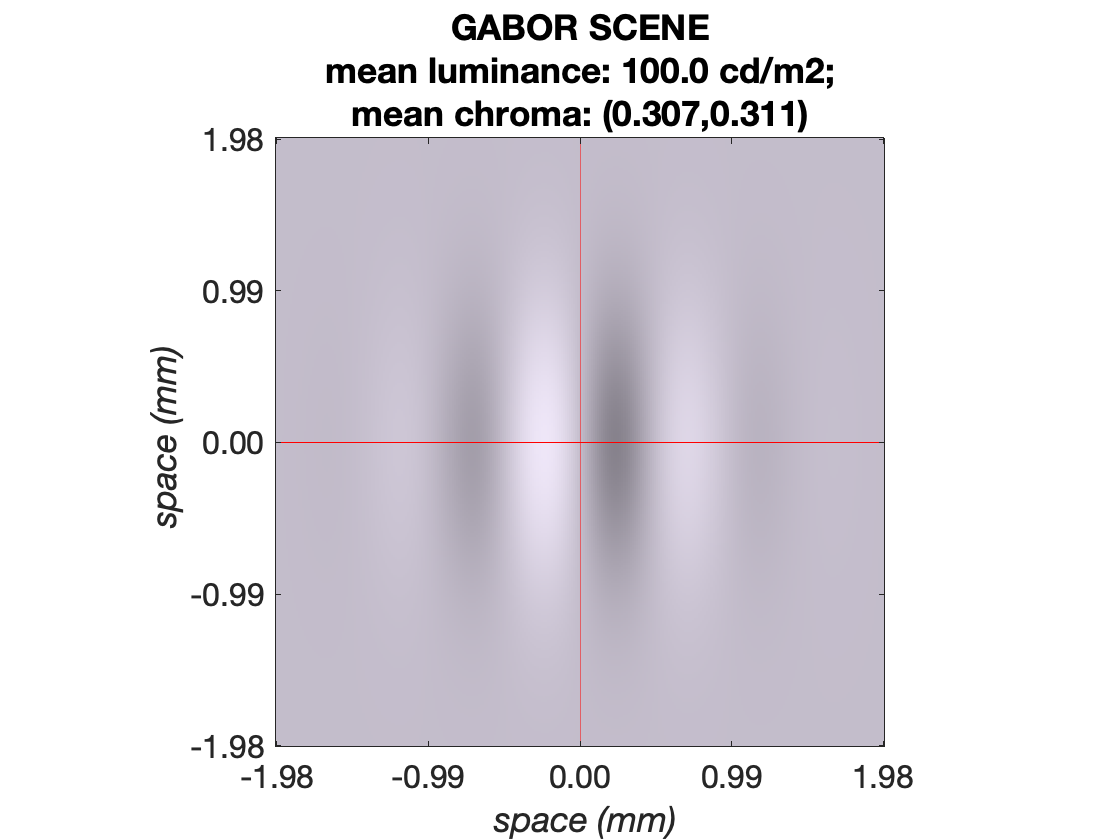

% retrieve the spatial support of the scene(in millimeters)
spatialSupportMilliMeters = sceneGet(scene, 'spatial support', 'mm');
% retrieve the sRGB components of the scene (just for visualization)
sceneRGBsettings = sceneGet(scene, 'rgb image');
% retrieve the XYZ tristimulus components of the scene
XYZmap = sceneGet(scene, 'xyz');
% compute the xy-chroma and the luminance maps
luminanceMap = squeeze(XYZmap(:,:,2));
xMap = squeeze(XYZmap(:,:,1))./sum(XYZmap,3);
yMap = squeeze(XYZmap(:,:,2))./sum(XYZmap,3);
% Compute mean luminance and mean chromaticity
meanLuminance = mean(luminanceMap(:));
meanChromaticity = [mean(xMap(:)) mean(yMap(:))];
% visualize the scene as RGB
visualizeSceneRGB(spatialSupportMilliMeters, 'mm', sceneRGBsettings, ...
    meanLuminance, meanChromaticity, sceneGet(scene, 'name'));

### Step 2.4 Plot the radiance of the scene

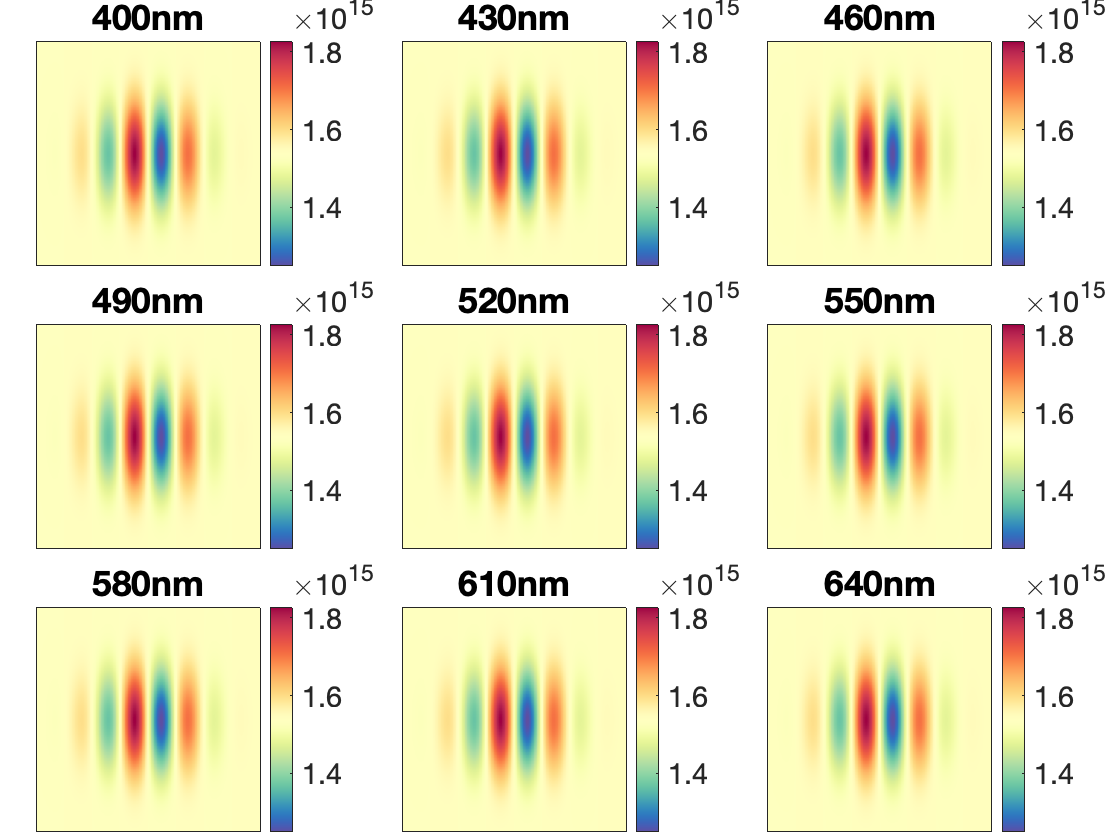

% retrieve the radiance of the scene as emitted photon rate 
% (photons/pixel/sec) per nm
scenePhotonRate = sceneGet(scene, 'photons');
% Retrieve wavelength support
wavelengthSupport = sceneGet(scene, 'wave');
wavelengthBandsToVisualize = 400:30:700;
visualizeSceneRadiance(spatialSupportMilliMeters, 'mm', ...
    scenePhotonRate, wavelengthSupport, wavelengthBandsToVisualize);

# **Step 3.** Create a scene object representing the stimulus as realized on the presentation display

### Step 3.1 Realize the stimulus scene onto the presentatio display

% Realize the scene into the presentation display
displayedScene = realizeSceneOnDisplay(scene, presentationDisplay);
% Give the scene a name
displayedScene = sceneSet(displayedScene, 'name', 'DISPLAYED GABOR SCENE');

### Step 3.2 Plot an RGB rendition of the displayed scene

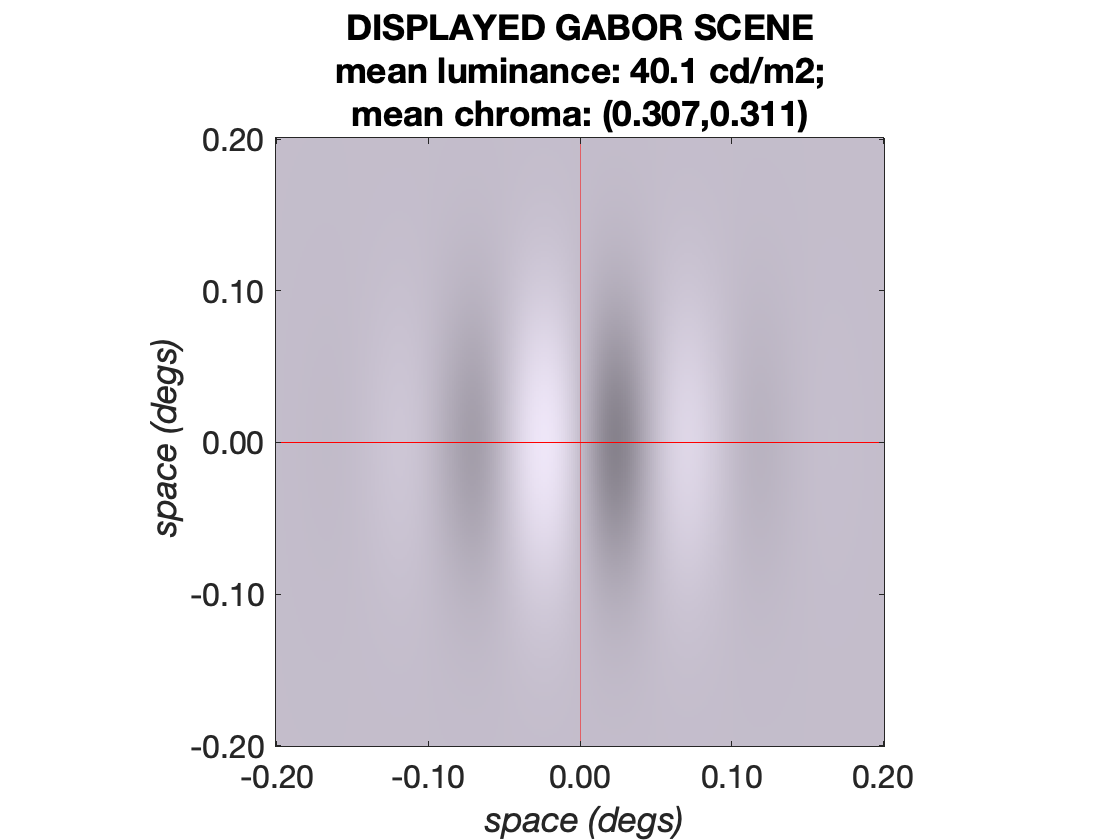

% retrieve the pixel size in degrees
pixelSizeDegs = sceneGet(displayedScene , 'w angular resolution');
% retrieve the pixel size in millimeters
pixelSizeMilliMeters = sceneGet(displayedScene , 'sample size', 'mm');
% compute degs/mm factor
degsPerMM = pixelSizeDegs/pixelSizeMilliMeters;
% retrieve spatial support in millimeters
spatialSupportMilliMeters = sceneGet(displayedScene , 'spatial support', 'mm');
% compute spatial support in degrees
spatialSupportDegs = spatialSupportMilliMeters * degsPerMM;
% retrieve the sRGB components of the scene (just for visualization)
sceneRGBsettings = sceneGet(displayedScene, 'rgb image');
% retrieve the XYZ tristimulus components of the scene
XYZmap = sceneGet(displayedScene, 'xyz');
% compute the xy-chroma and the luminance maps
luminanceMap = squeeze(XYZmap(:,:,2));
xMap = squeeze(XYZmap(:,:,1))./sum(XYZmap,3);
yMap = squeeze(XYZmap(:,:,2))./sum(XYZmap,3);
% Compute mean luminance and mean chromaticity
meanLuminance = mean(luminanceMap(:));
meanChromaticity = [mean(xMap(:)) mean(yMap(:))];
% visualize the scene as RGB
visualizeSceneRGB(spatialSupportDegs, 'degs', sceneRGBsettings, ...
    meanLuminance, meanChromaticity, sceneGet(displayedScene, 'name'));

### Step 3.3 Plot the radiance of the displayed scene

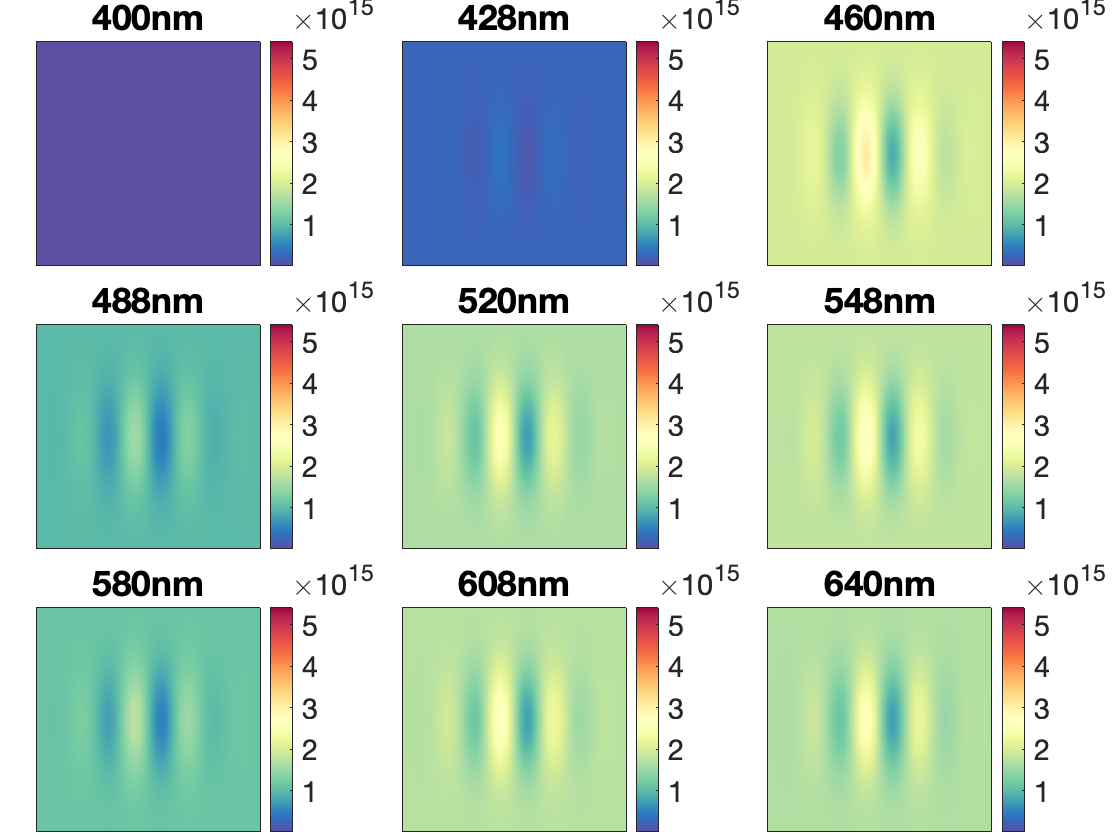

% retrieve the radiance of the scene as emitted photon rate 
% photons/sr/m^2/nm/sec
displayedScenePhotonRate = sceneGet(displayedScene, 'photons');
% Retrieve wavelength support
wavelengthSupport = sceneGet(displayedScene, 'wave');
wavelengthBandsToVisualize = 400:30:700;
visualizeSceneRadiance(spatialSupportMilliMeters, 'mm', displayedScenePhotonRate, ...
    wavelengthSupport, wavelengthBandsToVisualize);

# Step 4. Compare scene to displayed scene

% Pixel location to compare the spectral slices
targetLocationMM = [-0.15,-0.15];

### Step 4.1 Plot a spectral slice though a target pixel in the original scene

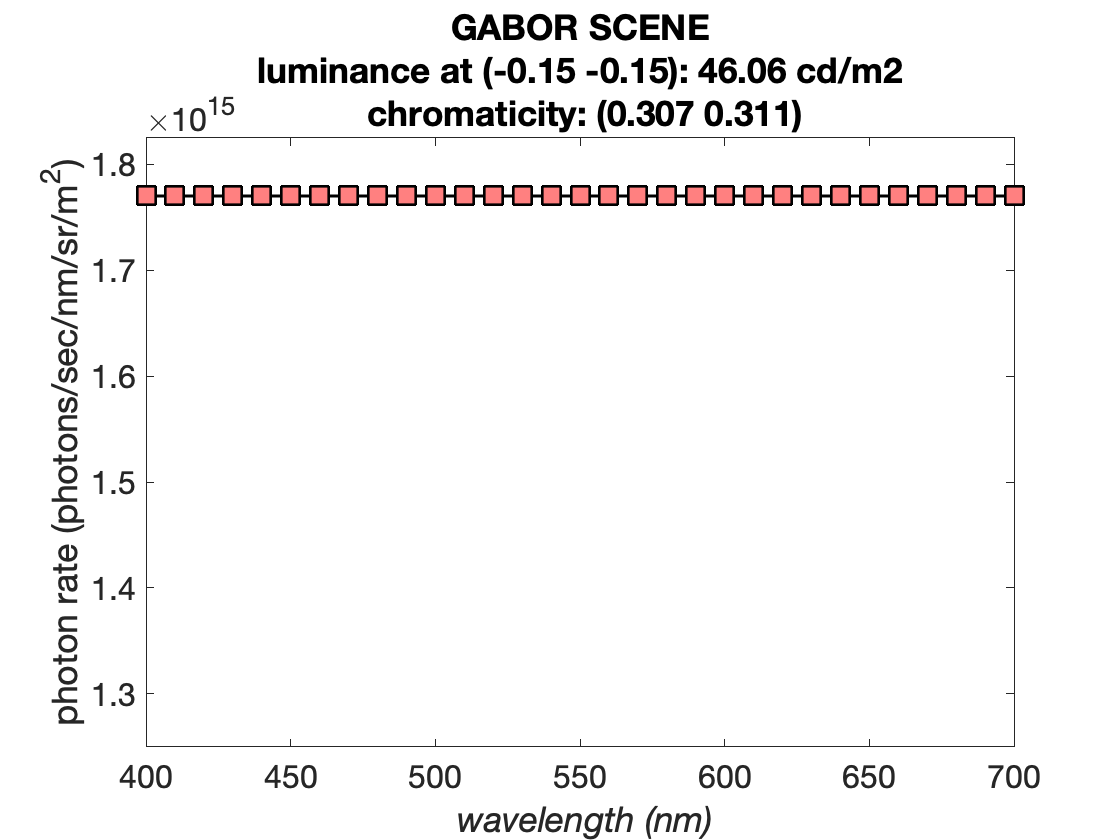

% retrieve the radiance of the scene as emitted photon rate (photons/pixel/sec) per nm
scenePhotonRate = sceneGet(scene, 'photons');
% retrieve the spatial support of the scene(in millimeters)
spatialSupportMilliMeters = sceneGet(scene, 'spatial support', 'mm');
% Retrieve wavelength support
wavelengthSupport = sceneGet(scene, 'wave');
visualizeSpectralRadianceSlice(spatialSupportMilliMeters, wavelengthSupport, ...
    scenePhotonRate, targetLocationMM,  sceneGet(scene, 'name'));

### Step 4.2 Plot a spectral slice though a target pixel in the displayed scene

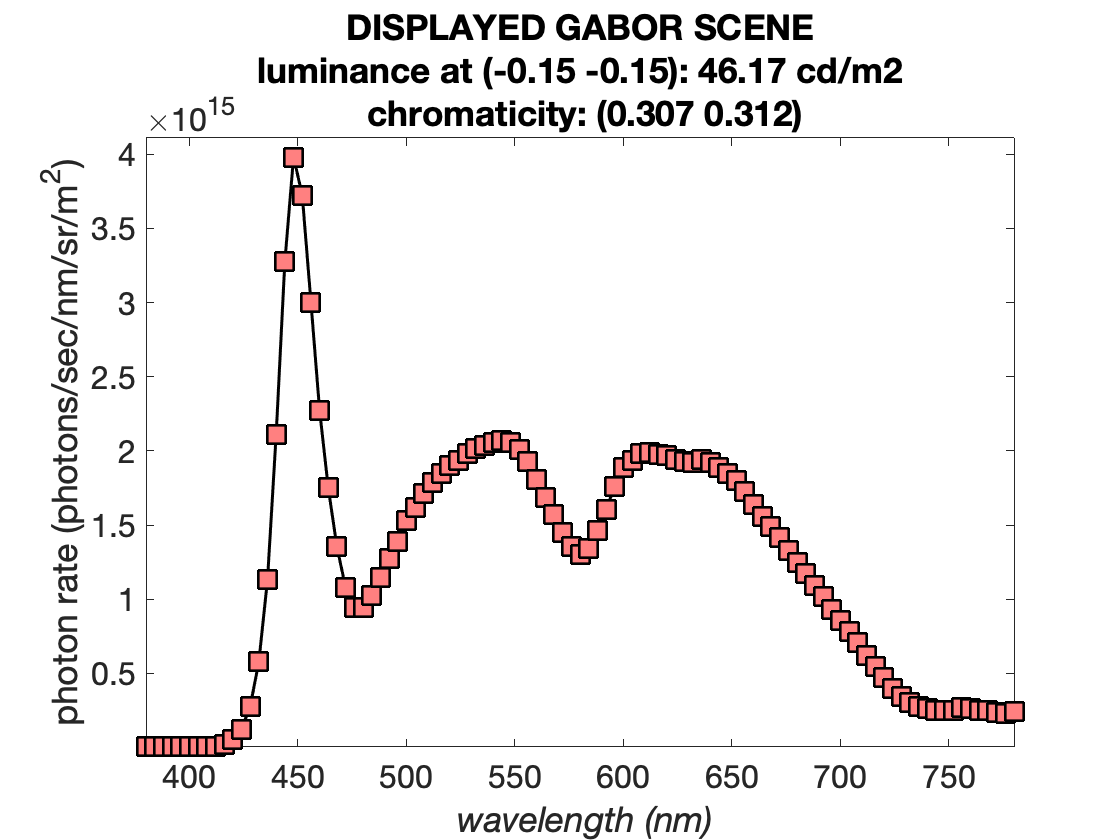

% retrieve the radiance of the scene as emitted photon rate (photons/pixel/sec) per nm
displayedScenePhotonRate = sceneGet(displayedScene, 'photons');
% retrieve the spatial support of the scene(in millimeters)
spatialSupportMilliMeters = sceneGet(displayedScene, 'spatial support', 'mm');
% Retrieve wavelength support
wavelengthSupport = sceneGet(displayedScene, 'wave');
visualizeSpectralRadianceSlice(spatialSupportMilliMeters, wavelengthSupport, ...
    displayedScenePhotonRate, targetLocationMM,  sceneGet(displayedScene, 'name'))